Consider the confound of the number of subjects.

group1: ratio of numbers of patients between sites

group2: ratio of numbers of HC between sites

sumGroup: ratio of numbers of subjects between sites

group1vsGroup2: ratio of (P/HC) between sites

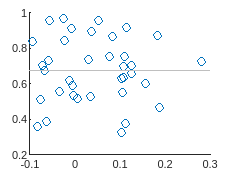

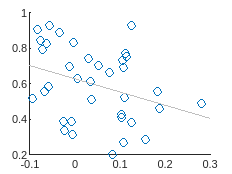

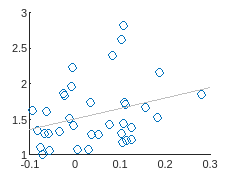

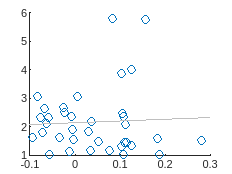

BD


                     group1      group2     sumGroup    group1vsGroup2
                     _______    ________    ________    ______________

    spearman corr    0.01287    -0.31532      0.2713       -0.18069   
    p                0.45609     0.01487    0.040745        0.15019   



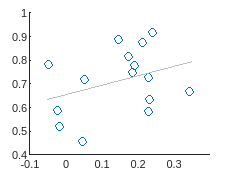

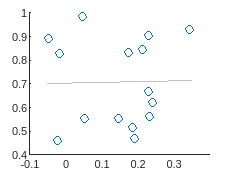

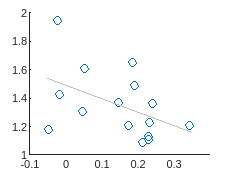

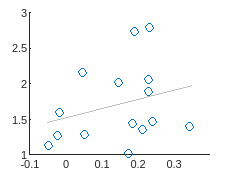

SCA


                     group1     group2     sumGroup    group1vsGroup2
                     _______    _______    ________    ______________

    spearman corr    0.18929    0.15357    -0.41071        0.36071   
    p                0.27247    0.25977     0.13789       0.060064   



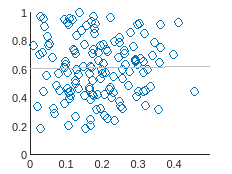

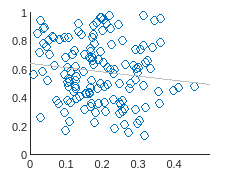

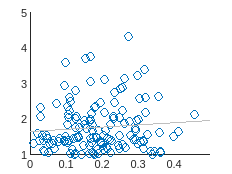

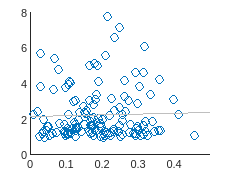

SCZ


                      group1       group2     sumGroup    group1vsGroup2
                     _________    ________    ________    ______________

    spearman corr    0.0036474    -0.12228    0.070155       0.031072   
    p                  0.46755     0.18643     0.27978        0.43544   



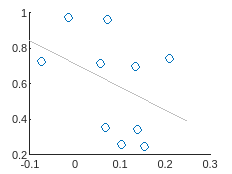

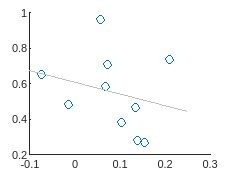

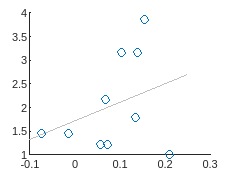

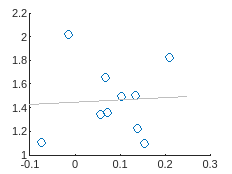

ASD


                      group1     group2     sumGroup    group1vsGroup2
                     ________    _______    ________    ______________

    spearman corr    -0.44242    -0.3697    0.24466       -0.042424   
    p                0.077359    0.12868    0.26345         0.39184   



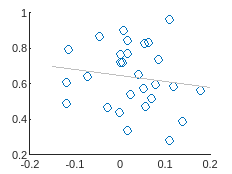

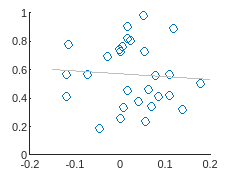

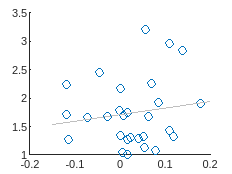

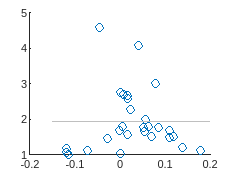

MDD


                      group1      group2      sumGroup    group1vsGroup2
                     ________    _________    ________    ______________

    spearman corr    -0.13957    -0.092501    0.095785       0.092501   
    p                 0.26161      0.33067     0.30365        0.33678   



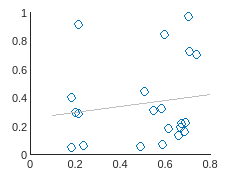

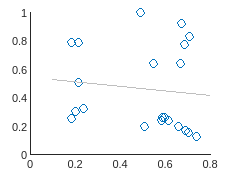

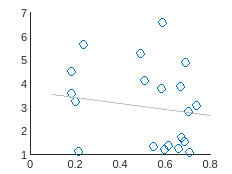

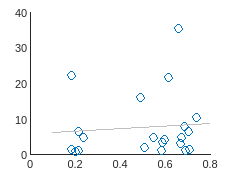

AD


                     group1      group2     sumGroup    group1vsGroup2
                     _______    ________    ________    ______________

    spearman corr    0.23636    -0.28098       -0.2        0.11039    
    p                0.16947    0.057016    0.16542        0.37097    



% Clear all variables and close all figures
clear all
close all

% Initialize parameters
iCOMBAT = 1; % Flag to determine if COMBAT harmonization is used
smoothKernel = 6; % Smoothing kernel size
iter = 5000; % Number of iterations for permutation testing
type = 'spearman'; % Correlation type (Spearman)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses to analyze

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT harmonization is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata about demographics and site information
metadata = readtable(['/projects/kg98/trangc/VBM/data/metadataVBM_extended.csv']);
% Load pre-computed correlation matrices and site lists
load(['output/corr_tmap_combat',num2str(iCOMBAT),'_smooth',num2str(smoothKernel),'.mat'], 'cor1', 'cor2',"siteList")

% Loop through each diagnosis
for iDiag = 1:nDiag
    % Compute variance related to illness duration and site correlation
    [varTable{iDiag} nSite{iDiag}]= cor_var_nPC(metadata, ...
        diagnosisString(iDiag), cor1{iDiag}, cor2{iDiag}, siteList{iDiag},iter, type);
% Display results if the variance table is not empty
    if size(varTable,1)~=0
        disp(char(diagnosisString(iDiag))); % Display diagnosis name
        disp(varTable{iDiag}); % Display variance table
        disp(' '); % Add spacing
        disp(' ')
    end
end


% Suppress specific warnings and save the results
warning('off','last')

Error using warning
The last warning issued had an empty warning identifier, or no warnings have yet been issued.

save('output/confound_nPC.mat','varTable','nSite')